Cruise control response

m = 1300;
b = 250;

kp0 = 1;
ki0 = 1;

[S,closedLoop] = cruiseResponse(m,b,kp0,ki0)

S = struct with fields:
        RiseTime: 539.9099
    SettlingTime: 965.6246
     SettlingMin: 0.9028
     SettlingMax: 0.9993
       Overshoot: 0
      Undershoot: 0
            Peak: 0.9993
        PeakTime: 1.7991e+03


closedLoop =
 
         s + 1
  --------------------
  1300 s^2 + 251 s + 1
 
Continuous-time transfer function.



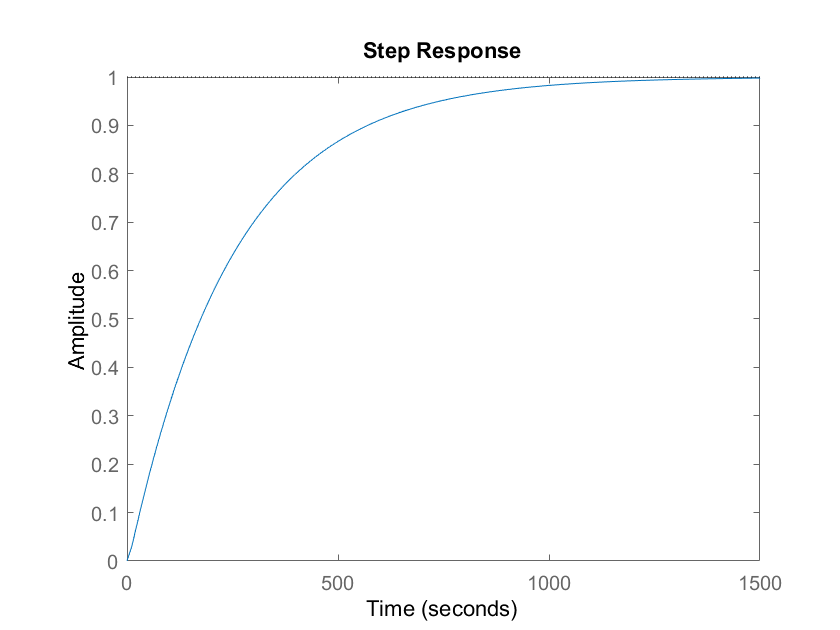


step(closedLoop)

Cruise control unconstrained optimization

% Set up the optimization
P0 = [kp0 ki0];
optimFunc = @(P) objFunc(P,m,b);

% Do a pattern search
tic
P = patternsearch(optimFunc,P0)

Maximum number of iterations exceeded: increase options.MaxIterations.


P = 	1.0e+60 *

    3.2139    0.0000


toc

Elapsed time is 3.801350 seconds.



% Look at the result
optimFunc(P)

ans = 7.8975e-115

[S,closedLoop] = cruiseResponse(m,b,P(1),P(2))

S = struct with fields:
        RiseTime: 8.8868e-58
    SettlingTime: 1.5824e-57
     SettlingMin: 0.9000
     SettlingMax: 1.0000
       Overshoot: 0
      Undershoot: 0
            Peak: 1.0000
        PeakTime: 4.2657e-57


closedLoop =
 
       3.214e60 s + 1024
  ----------------------------
  1300 s^2 + 3.214e60 s + 1024
 
Continuous-time transfer function.



closedLoop

closedLoop =
 
       3.214e60 s + 1024
  ----------------------------
  1300 s^2 + 3.214e60 s + 1024
 
Continuous-time transfer function.



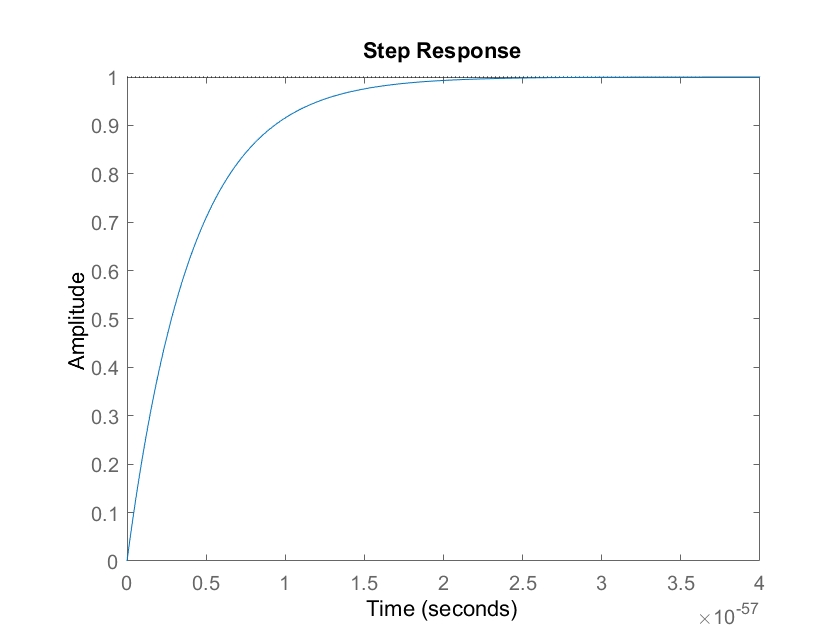

step(closedLoop)

function [obj] = objFunc(P,m,b)
    [S,~] = cruiseResponse(m,b,P(1),P(2));
    obj = S.RiseTime^2;
end

function [S,closedLoop] = cruiseResponse(m,b,kp,ki)

    % Set up the transfer functions
    plant = tf(1,[m b]);
    controller = pid(kp,ki,0);
    
    % Feedback transfer function
    closedLoop = feedback(plant*controller,1);

    % Get the step response characteristics
    S = stepinfo(closedLoop);
    
end